# Growth Kinetics Analaysis - w/ Stem Cells

clear;
clc;

## Wild Type

### n=1

Ctr_WT_1 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=1/results_from_time_0/location.dat";
[Ctr_WT_1_numberofcells, x, Ctr_WT_1_yLE, Ctr_WT_1_yME, Ctr_WT_1_yTotal, Ctr_WT_1_ME, Ctr_WT_1_LE] = TimeVsNoCells(Ctr_WT_1);

### n=2

Ctr_WT_2 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=2/results_from_time_0/location.dat";
[Ctr_WT_2_numberofcells, x, Ctr_WT_2_yLE, Ctr_WT_2_yME, Ctr_WT_2_yTotal, Ctr_WT_2_ME, Ctr_WT_2_LE] = TimeVsNoCells(Ctr_WT_2);

### n=3

Ctr_WT_3 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=3/results_from_time_0/location.dat";
[Ctr_WT_3_numberofcells, x, Ctr_WT_3_yLE, Ctr_WT_3_yME, Ctr_WT_3_yTotal, Ctr_WT_3_ME, Ctr_WT_3_LE] = TimeVsNoCells(Ctr_WT_3);

### n=4

Ctr_WT_4 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=4/results_from_time_0/location.dat";
[Ctr_WT_4_numberofcells, x, Ctr_WT_4_yLE, Ctr_WT_4_yME, Ctr_WT_4_yTotal, Ctr_WT_4_ME, Ctr_WT_4_LE] = TimeVsNoCells(Ctr_WT_4);

### n=5

Ctr_WT_5 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=5/results_from_time_0/location.dat";
[Ctr_WT_5_numberofcells, x, Ctr_WT_5_yLE, Ctr_WT_5_yME, Ctr_WT_5_yTotal, Ctr_WT_5_ME, Ctr_WT_5_LE] = TimeVsNoCells(Ctr_WT_5);

% combine data tables from all experiments into one table

yTotal_Ctr_WT = cat(2,Ctr_WT_1_yTotal,Ctr_WT_2_yTotal,Ctr_WT_3_yTotal,Ctr_WT_4_yTotal,Ctr_WT_5_yTotal);
yLE_Ctr_WT = cat(2,Ctr_WT_1_yLE,Ctr_WT_2_yLE,Ctr_WT_3_yLE,Ctr_WT_4_yLE,Ctr_WT_5_yLE);
yME_Ctr_WT = cat(2,Ctr_WT_1_yME,Ctr_WT_2_yME,Ctr_WT_3_yME,Ctr_WT_4_yME,Ctr_WT_5_yME);

% transpose data table
time = x.';
yTotal_Ctr_WT_ = yTotal_Ctr_WT.';
yLE_Ctr_WT_ = yLE_Ctr_WT.';
yME_Ctr_WT_ = yME_Ctr_WT.';

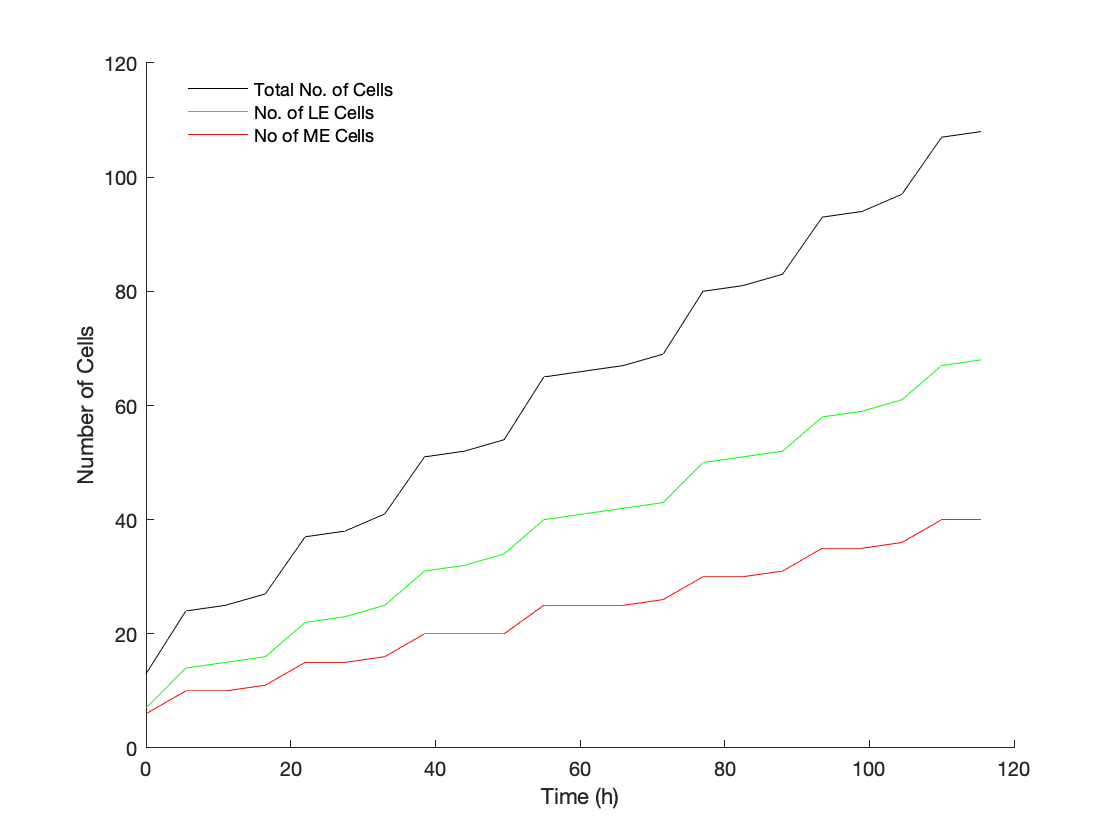

% plot data with error bars
clf

hold on; 

Ctr_WTtotal = shadedErrorBar(time(:,1:55:end),yTotal_Ctr_WT_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

hold on;

Ctr_WTLE = shadedErrorBar(time(:,1:55:end),yLE_Ctr_WT_(:,1:55:end),{@mean,@std},'lineProps','-g','transparent',1);
hold off;

hold on;

Ctr_WTME = shadedErrorBar(time(:,1:55:end),yME_Ctr_WT_(:,1:55:end),{@mean,@std},'lineProps','-r','transparent',1);

hold off;

ylabel ('Number of Cells')
xlabel('Time (h)')
legend({'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells'}, 'location', 'best')
legend('boxoff')
folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime_Ctr_WT.pdf');

movefile('FigureCellsvsTime_Ctr_WT.pdf', folder);

% combine data from all experiments
Ctr_WTnumberofcells = cat(1,Ctr_WT_1_numberofcells(end,:),Ctr_WT_2_numberofcells(end,:),Ctr_WT_3_numberofcells(end,:),Ctr_WT_4_numberofcells(end,:),Ctr_WT_5_numberofcells(end,:));

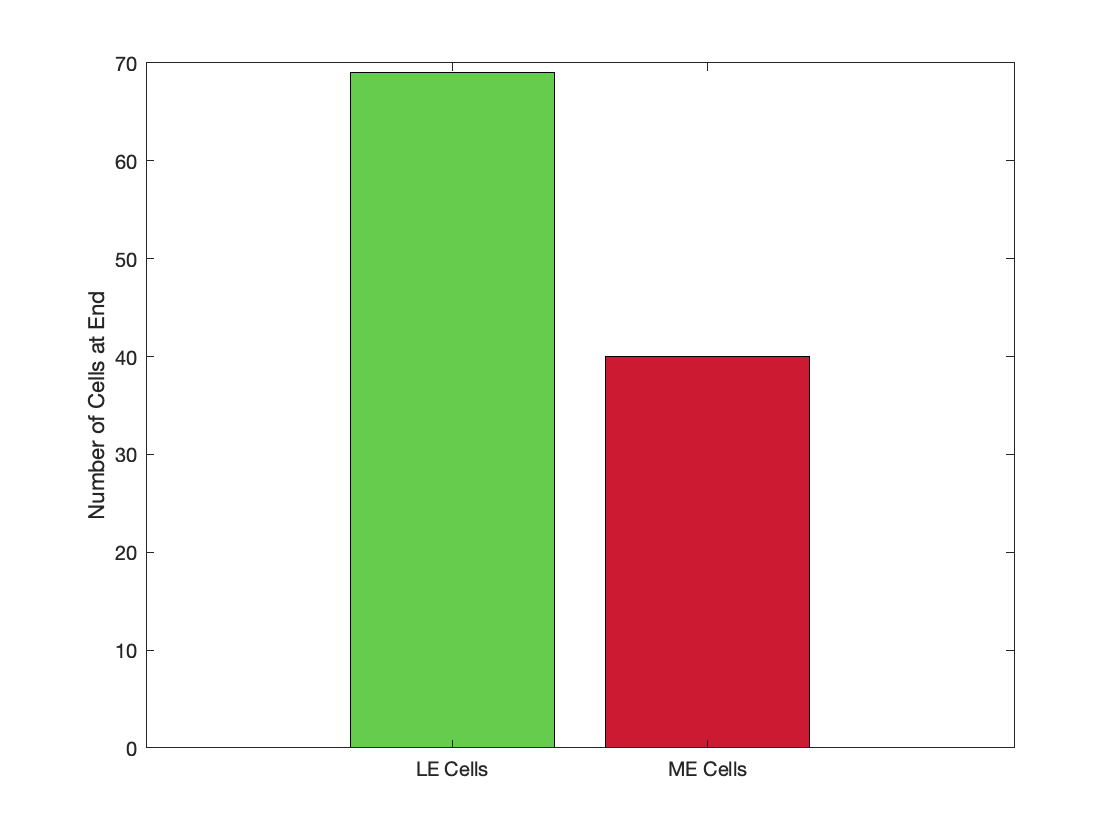

% plot data with error bars
x = [1 2];
Ctr_WTmeanLE = mean(Ctr_WTnumberofcells(:,1));
Ctr_WTmeanME = mean(Ctr_WTnumberofcells(:,2));
y = [Ctr_WTmeanLE,Ctr_WTmeanME];

b = bar(x,y);
ylabel('Number of Cells at End')
ax = gca;
ax.XTick = [1 2]; 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

folder = '~/Desktop/';
exportgraphics(gca, 'CellCount_Ctr_WT.pdf');